# Exploring Sequences

## Introduction

In this activity we will explore sequences $\{a_n\}$ geometrically and symbolically. 

First we will use the command [`stem`](https://au.mathworks.com/help/matlab/ref/stem.html) to plot sequences and try to determine whether they converge or diverge. Then we will determine the limit of particular sequences using the commands [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`limit`](https://au.mathworks.com/help/symbolic/limit.html). Finally, you will need to write some code to solve the problem at the end.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read carefuly each section. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

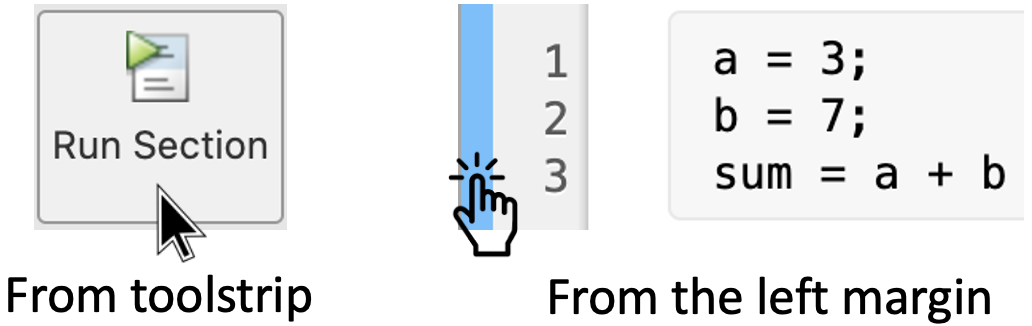

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Geometric exploration

### 1.1 Set up

Consider the following sequences

a) $a_n =\sin \left({\left(-2\right)}^n \right)$  and    b) $b_n =\frac{2n^3 }{n^3 -4}$ .

To plot these sequences, first, let's create a variable:

max = 59

**Note 1:** This variable is an integer defined between 1 and 150.

We need to use the command [`linspace`](https://au.mathworks.com/help/matlab/ref/linspace.html) to define the domain of the sequences. In this case we can store this information as a variable:

n = linspace(1, max, max);

Now we can define our sequences as follows:

an = sin((-2).^n);
bn = (2*n.^3)./(n.^3-4);

**Note 2: **Notice that the operations *multiplication*, *division* and *potentiation* need to be vectorised. For that reason you have to add the *period *(.) before each operator: `*, /, ^`. Learn more about it here: [Arithmetic operations](https://au.mathworks.com/help/matlab/arithmetic-operators.html).

### 1.2 Plotting sequences

Finally, we plot each sequence separately:

stem(n, an, 'filled')
stem(n, bn, 'filled')

Drag the slider of the variabe **max **defined in line 1, to show more terms of the sequences on the plots.

### 1.3 Compare sequences

You can compare the sequences by plotting them together as follows:

m = linspace(1, 100, 100)';
cm = [sin((-2).^m), (2*m.^3)./(m.^3-4)];
stem(m, cm, 'filled')

**Note :** Observe that we added the symbol (') just before (;) of line 7 to plot two data series using a two-column matrix.

### **Task 1:**

Modify **line 7** on the previus code to plot more values of the sequences. What do you notice?

## Question:

Based on the graphs of the sequences, which one converges? Which one diverges?

## 2. Symbolic exploration

### 2.1 Calculating limits symbolically

Calculating limits of sequences in MATLAB is quite easy. We just need the command [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`limit`](https://au.mathworks.com/help/symbolic/limit.html). For example, let's calculate the limit of

${c_n =\left(\frac{2n-3}{3n-7}\right)}^4$.

Here we need to create a *symbolic variable* for 'n', that is:

syms n

Then we just calculate the limit as follows:

limit(((2*n-3)/(3*n-7))^4, n, inf)

### 2.2 Comparing results

We will calculate the limits of $a_n =\sin \left({\left(-2\right)}^n \right)$ and $b_n =\frac{2n^3 }{n^3 -4}$, defined at the beginning. 

### **Task 2:** 

But before running the code in this section, remember the behaivour of these sequences based on the plots we have made previuosly. Make a pause and think what would be the limit of each one of them. Once you have done this, run the following lines:

ans1 = limit(sin((-2)^n), n, inf) % limit of sequence a_n
ans2 = limit((2*n^3)/(n^3-4), n, inf) % limit of sequence b_n

### **Questions:**

What do you notice? What happens to the results **ans1** and **ans2**? Can you confim the results using the theorems covered in class?

## 3. Activity

Let's practice what we just learned. 

a) Use the commands [`linspace`](https://au.mathworks.com/help/matlab/ref/linspace.html) and [`stem`](https://au.mathworks.com/help/matlab/ref/stem.html) to plot 150 terms of the following sequences.

- 
$$\frac{2^k +1}{e^k }$$


- 
$$2+\cos \left(k\;\pi \right)$$


- 
$${\left(-2\right)}^{k+1}$$


- 
$$\frac{\sin \left(k+\pi \right)}{k^3 }$$


**Hint 1:** In this case you have to define a variable `k`. Also check the previous examples to type correctly the syntax of the arithmetic operations.

**Hint 2:** In MATLAB the constant $\pi$ is defined as `pi`. The constant $e\approx 2\ldotp 71828$ can be defined using the function [`exp`](https://au.mathworks.com/help/matlab/ref/exp.html), that is, `exp(1)`.

b) Find the limits of each sequence using the commands [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`limit`](https://au.mathworks.com/help/symbolic/limit.html).

**Hint 3:** To add comments to MATLAB code, use the percent (`%`) symbol. Comment lines can appear anywhere in a program file, and you can append comments to the end of a line of code.

### 3.1 Solution to part a)

Write your code here:

### 3.2 Solution to part b)

Write your code here: